**Algorithm for getting Ackerman error**

The purpose of this algorithm is to get the average Ackerman error of a steering system given its dimensions and steering knuckle angle. 

The steering mechanism that will be used is rack-pinion.

A commercial vehicle rack will be chosen based on our needs. Some of the current options are: 

1) 

% Dimensions (cm)
k_arm = 10;     % arm connected to knuckle 
t_rod = 21;   % intermediate arm
rack = 35;
track = 80;    % wheelbase width
d = 18.72;     % Distance between rack & front chassis
tire = 15; 

% Angles
gamma_l = 27; gamma_r = 27; % Angles between tie rod and rack projection
alpha = 22;  % Angle between tire and knuckle arm (fixed angle)
steer = -10;   % Steering angle
beta = 90 - alpha + steer  % whole angle between tire and front chassis

beta = 58


% Cosine law for calculating angles to display tire in plot (B = tire/2, C
% = knuckle arm)  ---  tire inside the turn
B = tire / 2;
C = k_arm;
A = sqrt(B^2 + C^2 - 2 * B * C * cos(deg2rad(alpha)))         % Distance from start of knuckle arm to bottom point of tire

A = 4.1440

theta = rad2deg(acos((-B^2 + A^2 + C^2) / (2 * A * C)))

theta = 42.6865

bottom_tire = 180 - (180 - (beta + alpha)) - (alpha + theta)  % Angle of the bottom point of the tire to the horizontal axis

bottom_tire = 15.3135


figure(); title('Steering mechanism')
hold on; grid on; xlim([-50 50]); ylim([-25 75]);
plot(0, 0, 'bo', MarkerSize=5);
% Track
plot(-track/2, d, 'ro', MarkerSize=5);
plot(track/2, d, 'ro', MarkerSize=5);
plot([-track/2, track/2], [d,d], 'k', LineWidth=2);
% Dist
plot(0, d, 'ro', MarkerSize=5);
plot([0, 0], [d, 0], 'k', LineWidth=1.5, LineStyle='--');
% Inner tire (in turn)
tire_point = [-A * cos(deg2rad(bottom_tire)) + left_tie(1) , A * sin(deg2rad(bottom_tire)) + left_tie(2)];
tire_point_up = [-track/2 - (tire/2) * cos(deg2rad(steer + 90)), d + (tire/2) * sin(deg2rad(90 + steer))];
plot(tire_point(1), tire_point(2), 'ko', MarkerSize=1.5);
plot(tire_point_up(1), tire_point_up(2), 'ko', MarkerSize=1.5);
plot([tire_point(1), tire_point_up(1)], [tire_point(2), tire_point_up(2)], LineWidth=2, Color='k')
% Steering wheel angle
plot([-track/2, -track/2], [d, d+20], LineStyle='--', LineWidth=1, color='k')
% Ending tie rod (begin of knuckle arm)
tie_rod = [-track/2 + k_arm * cos(deg2rad(beta)), d - k_arm * sin(deg2rad(beta))];
plot(tie_rod(1), tie_rod(2), 'bo', MarkerSize=2);
plot([-track/2, tie_rod(1)], [d, tie_rod(2)], LineWidth=2, Color='k');
% Tie rod calculations (cosines)
B = tie_rod(2); % take the vertical distance to origin of that point
C = t_rod;      % hypotenuse = tie rod length
A = sqrt(C^2 - B^2);  % Pythagorean
gamma_l = rad2deg(acos((A^2 + C^2 - B^2) / (2 * A * C))) % Cosine law to get angle between rack and horizontal

gamma_l = 29.1827

in_mid = 270 - (90 - gamma_l) - beta  % Mid angle (k_arm / tie rod)

in_mid = 151.1827

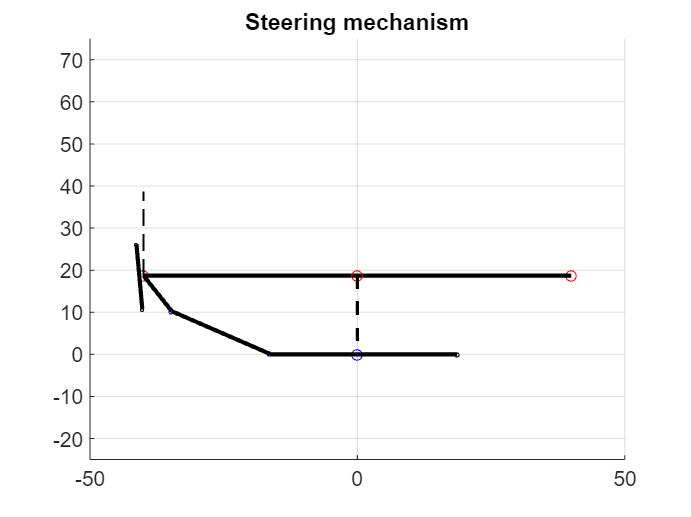

rack_l = [tie_rod(1) + t_rod * cos(deg2rad(in_mid - (180 - beta))), tie_rod(2) - t_rod * sin(deg2rad(in_mid))];
plot(rack_l(1), rack_l(2), 'bo', MarkerSize=2);
plot([tie_rod(1), rack_l(1)], [tie_rod(2), rack_l(2)], LineWidth=2, Color='k');
% Rack
rack_r = [rack_l(1) + rack, 0];
plot(rack_r(1), rack_r(2), 'ko', MarkerSize=2);
plot([rack_l(1), rack_r(1)], [0, 0], LineWidth=2, color='k')